# PID系数整定

之前，利用simulink通过观察等幅震荡，使用“扩充临界比例度法”整定得到的PID参数如下：

getPID1


pidsys1 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 0.827, Ki = 2.5, Kd = 0.0781, Ts = 0.00945
 
Sample time: 0.0094528 seconds
Discrete-time PID controller in parallel form.



getPID2


pidsys2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 6.84, Ki = 18.5, Kd = 0.723, Ts = 0.0106
 
Sample time: 0.010583 seconds
Discrete-time PID controller in parallel form.



## 使用pidtune函数进行整定

%使用Matlab自带工具进行PID系数的整定
Ts=0.01;
Tf=0;
Gp1=tf(5,conv([0.5 1],[0.1 1]));
Gp1d=c2d(Gp1,Ts,'zoh');
Gp2=tf(1,conv([1 0],[0.1 1]));
Gp2d=c2d(Gp2,Ts,'zoh');
%PID系数整定
C1 = pidtune(Gp1d,'PID')


C1 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 0.421, Ki = 1.06, Kd = 0.0417, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PID controller in parallel form.



C2 = pidtune(Gp2d,'PID')


C2 =
 
              Ts            z-1 
  Kp + Ki * ------ + Kd * ------
              z-1           Ts  

  with Kp = 27.2, Ki = 47.4, Kd = 1.76, Ts = 0.01
 
Sample time: 0.01 seconds
Discrete-time PID controller in parallel form.



## 绘制闭环阶跃响应曲线

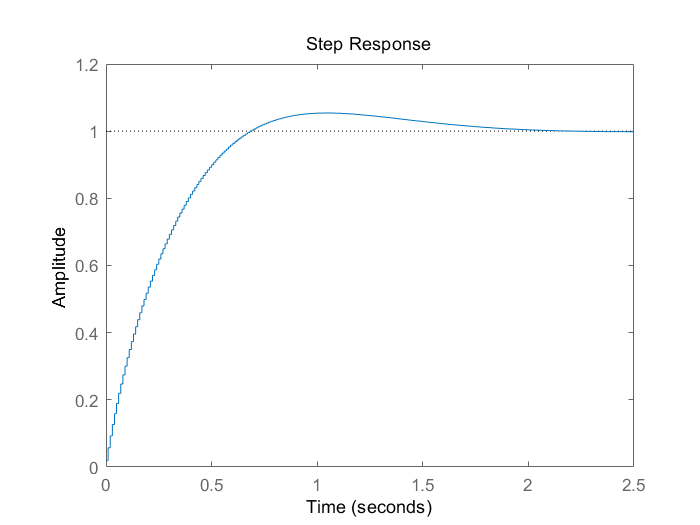

Phi1=feedback(series(C1,Gp1d),1);
stepplot(Phi1);

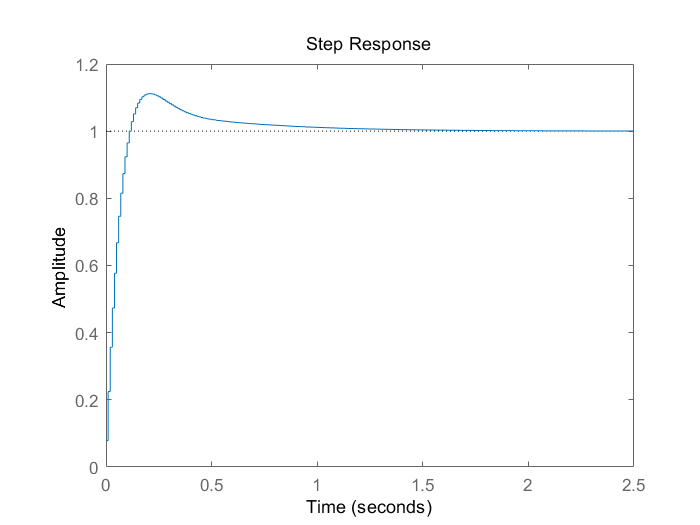

Phi2=feedback(series(C2,Gp2d),1);
stepplot(Phi2);